function [Y, freq] = make_spectrum(signal, fs)
    % make_spectrum - Computes the complex spectrum of a signal
    % 
    % Syntax: [Y, freq] = make_spectrum(signal, fs)
 

    % Compute the FFT of the signal
    Y = fft(signal);
    
    % Scale the FFT to give a physically plausible scaling
    Y = Y / length(Y);
    
    % Frequency resolution
    delta_f = fs / length(signal);
    
    % Frequency vector
    freq = 0:delta_f:(fs - delta_f);
    
    % Convert into column vectors (if required)
    Y = Y(:);
    freq = freq(:);
end

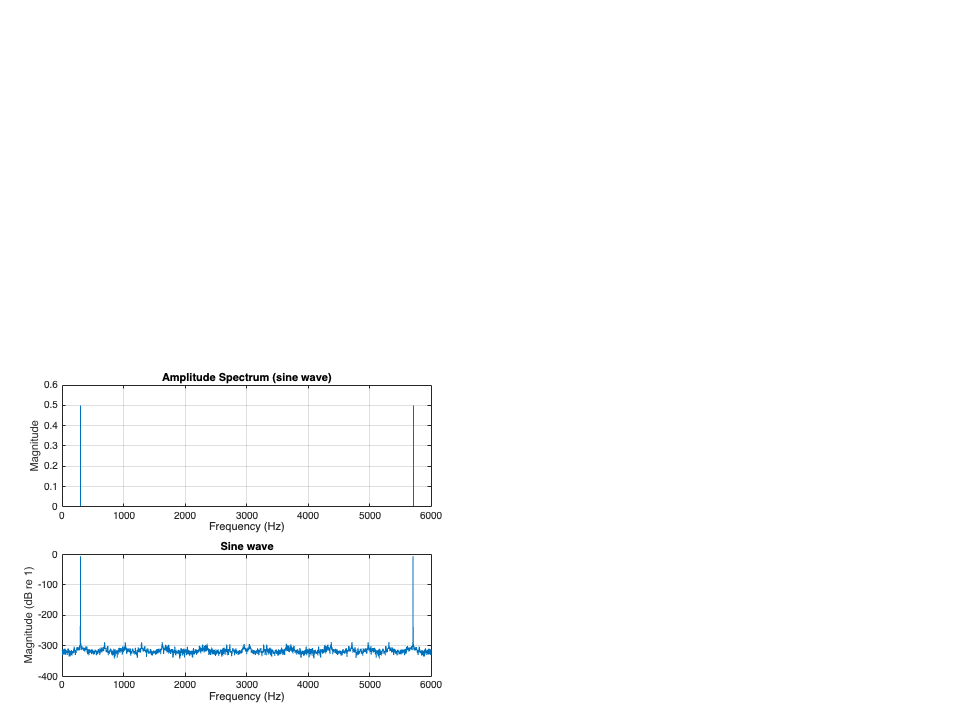

% created signal

% Parameters
Fs = 6000; % Sampling frequency (Hz)
T = 0.5; % Total time (seconds)
f = 300; % Signal frequency (Hz)

% Time vector
t = 0:1/Fs:T-1/Fs;

% Signal
signal = sin(2*pi*f*t);

% Call the make_spectrum function
[Y, freq] = make_spectrum(signal, Fs);

% Plot the amplitude spectrum
figure;

% First subplot: Amplitude vs Frequency
subplot(2,1,1);
stem(freq, abs(Y), 'Marker', 'none');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Amplitude Spectrum (sine wave)');
grid on;

% Convert the magnitude spectrum to dB scale
signal_dB = 20 * log10(abs(Y));

% Second subplot: dB vs Frequency
subplot(2,1,2);
plot(freq, signal_dB); % Use plot for continuous line
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB re 1)');
title('Sine wave');
grid on;

% Signal with noise


clear all;

% Specify the filename
filename = 'Skovbrynet 2G.m4a';

% Read the audio file
[audioData, sampleRate] = audioread(filename);

% Cut the audio to 0.5 seconds
duration = 0.5; % Duration in seconds
numSamples = min(round(sampleRate * duration), length(audioData));
audioData = audioData(1:numSamples);

% Time vector for the x-axis in seconds
timeVector = (0:numSamples-1) / sampleRate;

% Plot the amplitude vs. time in the discrete domain
figure;
subplot(3,1,1); % Create a subplot for time domain
stem(timeVector, audioData, 'Marker', 'none');
xlabel('Time (s)');
ylabel('Amplitude');
title('Amplitude vs. Time (Discrete Domain)(audio signal)');
grid on;

% Use the make_spectrum function to compute the spectrum
[Y, freq] = make_spectrum(audioData, sampleRate);

% Plot the amplitude vs. frequency in the discrete domain
subplot(3,1,2); % Create a subplot for frequency domain
stem(freq, abs(Y), 'Marker', 'none');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Amplitude vs. Frequency (Discrete Domain)(audio signal)');
grid on;

% Adjust x-limits to focus on the relevant frequency range
xlim([0 3000]); % Show only the range between 0 and 3000 Hz

% Convert the spectrum to dB
signal_dB = 20 * log10(abs(Y));

% Plot the dB vs. frequency using a continuous line plot
subplot(3,1,3); % Create a third subplot for dB scale
plot(freq, signal_dB); % Use plot for continuous line
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB re 1)');
title('Amplitude vs. Frequency (dB Scale) (audio signal)');
grid on;

% Zoom into the frequency range of 0 to 3000 Hz for dB plot
xlim([0 3000]); % Show only the range between 0 and 3000 Hz

% Clear all variables
clear all;

%% Parameters for the sine wave signal
Fs = 6000; % Sampling frequency (Hz)
T = 0.5;   % Total time (seconds)
f = 300;   % Signal frequency (Hz)

% Time vector
t = 0:1/Fs:T-1/Fs;

% Sine wave signal
signal = sin(2*pi*f*t);

% Call the make_spectrum function to get the spectrum for the sine wave
[Y_sine, freq_sine] = make_spectrum(signal, Fs);

% Convert the magnitude spectrum to dB scale for the sine wave
signal_sine_dB = 20 * log10(abs(Y_sine));

%% Load and process the audio signal
% Specify the filename
filename = 'Skovbrynet 2G.m4a';

% Read the audio file
[audioData, sampleRate] = audioread(filename);

% Cut the audio to 0.5 seconds
duration = 0.5; % Duration in seconds
numSamples = min(round(sampleRate * duration), length(audioData));
audioData = audioData(1:numSamples);

% Call the make_spectrum function to get the spectrum for the audio signal
[Y_audio, freq_audio] = make_spectrum(audioData, sampleRate);

% Convert the magnitude spectrum to dB scale for the audio signal
signal_audio_dB = 20 * log10(abs(Y_audio));

%% Plot both dB vs Frequency plots on the same figure
figure;

% Plot dB vs Frequency for the sine wave signal
plot(freq_sine, signal_sine_dB, 'b-', 'LineWidth', 1.5);
hold on; % Keep the figure for the second plot

% Plot dB vs Frequency for the audio signal
plot(freq_audio, signal_audio_dB, 'r--', 'LineWidth', 1.5);

% Set x-limits to focus on the relevant frequency range (adjust as needed)
xlim([0 3000]); % Adjust the range based on your requirements

% Add labels and title
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB re 1)');
title('dB vs Frequency Plot for Sine Wave and Audio Signal');

% Add a legend to distinguish between the two signals
legend('Sine Wave Signal', 'Audio Signal');

% Add grid
grid on;

% Display the combined plot
hold off;